#                           Optimization With First Order Stochastic Dominance

Cleaning Workspace,Command Window and Fomatting numeric type to long. 

clear;
clc;
close all;
format long;

The following two arrays of strings contains list of BSE Companies and their tickers respectively.

Company = {'Infosys','Axis Bank','Asian Paints','Bajaj Auto', 'Bajaj Finance','Bajaj Finserv','Bharti Airtel','HCL', 'HDFC Bank','HDFC', 'Hindustan Unilever','ICICI','IndusInd Bank', 'ITC' ,'Kotak Mahindra Bank', 'L&T','Mahindra & Mahindra','Maruti Suzuki','Nestle','NTPC' ,'ONGC','Power Grid Corporation of India' ,'Reliance Industries' ,'SBI','Sun Pharmaceutical Industries','Tata Steel' ,'TCS', 'Tech Mahindra' ,'Titan','UltraTech Cement'};
tickers = {'INFY.BO','AXISBANK.BO','ASIANPAINT.BO','BAJAJ-AUTO.BO','BAJFINANCE.BO','BAJAJFINSV.BO','BHARTIARTL.BO','HCLTECH.BO','HDFCBANK.BO','HDFC.BO','HINDUNILVR.BO','ICICIBANK.BO','INDUSINDBK.BO','ITC.BO','KOTAKBANK.BO','LT.BO','M&M.BO','MARUTI.BO','NESTLEIND.BO','NTPC.BO','ONGC.BO','POWERGRID.BO','RELIANCE.BO','SBIN.BO','SUNPHARMA.BO','TATASTEEL.BO','TCS.BO','TECHM.BO','TITAN.BO','ULTRACEMCO.BO'};

To download the data from yahoo finance we are using [Yahoo Finance and Quandl data downloader ](https://in.mathworks.com/matlabcentral/fileexchange/68361-yahoo-finance-and-quandl-data-downloader)package.The function getMarketDataViaYahoo() contains the arguments ticker symbol, start date, end date and the frequency by which we want the data.Here we are taking daily prices of stocks.We are downloading the SENSEX values till today's date.

data2 = getMarketDataViaYahoo('^BSESN', '1-Aug-2020', datetime('today'), '1d');
Index = data2(:,"AdjClose");

The 1st column of stock prices stored in all_stock_prices is date and each stock's price in next columns for all the tickers mentioned in the tickers array.

all_stock_prices(:,"Date") = data2(:,"Date");
n = length(tickers);
for i=1:n
   data = getMarketDataViaYahoo(tickers{i}, '1-Aug-2020', datetime('today'), '1d');
  all_stock_prices(:,Company{i}) = data(:,"AdjClose");
end

The price2ret function converts all our stock price and index arrays into their respective return's array. 

Index_ret = price2ret(table2array(Index));
A = table2array(all_stock_prices(:,2:end)); 
all_stock_returns = price2ret(A);

[m,n] = size(all_stock_returns);
u = ones(n,1);
p = 1/m;
c = zeros(m,1);
for i=1:m
    for j=1:m
        if Index_ret(i) >= c(j)
            c(i) = c(i)+1;
        end
    end
end

We are using Optimisation toolbox to solve our optimisation equations and constraints.

clear fsd_problem;
fsd_problem = optimproblem;

 x is the optimization variable that is used in the problem which represents weights.

x = optimvar('x',n,'Lowerbound',0,"UpperBound",1);

Objective function is maximizing expected return.

fsd_problem.ObjectiveSense = 'maximize';
fsd_problem.Objective = p*sum(all_stock_returns*x);

Constraint 1:

fsd_problem.Constraints.c1 = x'*u ==1 ;

Constraint 2:

const1 = optimconstr(m,1);
for j=1:m
    expr = fcn2optimexpr(@constraintfunction,Index_ret,all_stock_returns,x,j,m);
    const1(j) = expr <=  c(j);
end
fsd_problem.Constraints.c2 = const1; 

In non linear optimisation we neet to give a starting variable in the form of struct as x0.  

clear x0;
x0.x(1:n)=ones(1,n);
[sol,fval] = solve(fsd_problem,x0);

Solving problem using fmincon.

Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


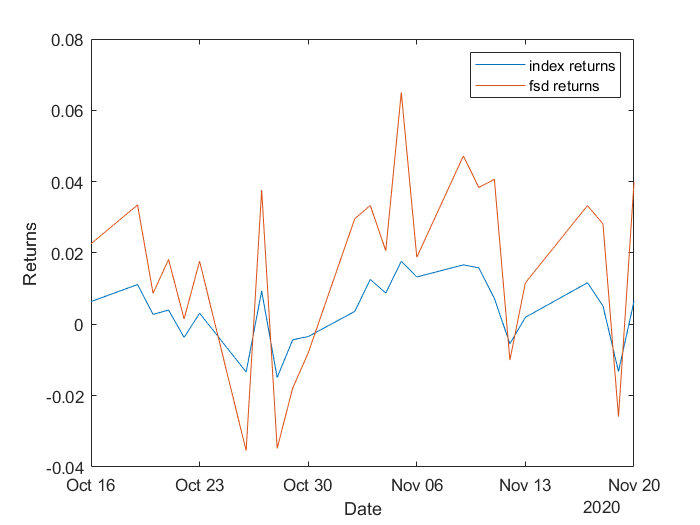

plot(table2array(all_stock_prices(2:end,1)),Index_ret);
hold on;
plot(table2array(all_stock_prices(2:end,1)),all_stock_returns*(sol.x));
legend('index returns','fsd returns');
xlabel('Date'); ylabel('Returns');


portfolio = ["Index","FSD"]';
mean_return = [sum(Index_ret(:))/n,sum(all_stock_returns*(sol.x))/n]';
min_return   = [min(Index_ret(:)),min(all_stock_returns*(sol.x))]';
max_retunrn  = [max(Index_ret(:)),max(all_stock_returns*(sol.x))]';
std_return   = [std(Index_ret(:)),std(all_stock_returns*(sol.x))]';
T = table(portfolio,mean_return,min_return,max_retunrn,std_return)

T = 2×5 table
    portfolio        mean_return            min_return            max_retunrn            std_return     
    _________    ___________________    ___________________    __________________    ___________________

     "Index"     0.00331477858279552    -0.0149084465810621    0.0176688884186014    0.00928019225453991
     "FSD"        0.0138158159019992    -0.0354093715653983    0.0650336361445877     0.0262127816718188


function constr = constraintfunction(Index_ret,all_stock_returns,w1,j,m)
    constr = sum((Index_ret(j)*ones(m,1)-(all_stock_returns*w1))>0);  
end
